### Calculating direct and indirect costs of dispersal

#### Parameters and definitions

For each model, we define:

$D$: the maximum displacement distance

nmax: the maximum larval navigation ability

We also define several distance-dependent parameters.

$f_i$ : the cost of navigating distance i

$c_i$: the cost of displacing distance i

$v_i$: the probability of displacing distance i, according to the displacement strategy

We also define two distance-dependent quantities based on the seascape. For our 2 x $\infty$ seascape (actually 2 x 512, but we'll assume infinite length for these purposes), they have the following values:

$n_i$: the total number of sites at distance i from a focal site. $n_0 = 1$ and $n_i=4i$ for $i>0$.

$g_i$: the number of sites (at distance i from a focal site) to which displacement is nonlethal. i.e., either viable sites, or within navigation distance of a viable site.

- when nmax=0: $g_0=1$, $g_1=3$, and $g_i=4$ for $i>1$.

- when nmax=1: $g_0=1$, $g_1=4$, $g_2=7$, and $g_i=8$ for $i>2$.

- when nmax=2: $g_0=1$, $g_1=4$, $g_2=8$, $g_3=11$ and $g_i=12$ for $i>3$.

For two sites at distance $i$ from one another, we can then calculate $L_i$, the expected number of larvae displacing from the origin to the destination site:

$L_i = \frac{1}{n_i}(1-c_i)v_i$.

#### Direct Cost

The direct cost of dispersal is the cost due to larval mortality. In our model, this is the probability of landing in a nonviable site (combined with any distance-specific dispersal mortality specified as a parameter). The direct cost of dispersal to distance $i$ can be expressed as:


$$M_i = c_i + (1-c_i)(1-\frac{g_i}{n_i})$$


#### Indirect Cost

The indirect cost of dispersal is the cost due to kin competition. For a given distance, consider a focal larva that disperses that distance. The indirect cost can be expressed as the fraction of total competitors at that site who are siblings of the focal larva -- i.e., the number of siblings ($S_i$) divided by the total number of competitors ($T_i$).


$$K_i = \frac{S_i}{T_i}$$


We will consider the numerator and denominator separately. 

First, the number of siblings ($S_i$). We define this quantity for distance $i$ and larval navigation abilities $nmax = 0,1,2$. In each case, we calculate the total expected number of larvae expected to disperse (displace+navigate) from a focal site to a given site at distance $i$. Then we subtract 1, to account for the focal larva (i.e., calculate how many siblings it shares the site with, not counting itself).

$S_{0,i} = L_i -1$.

When there is no navigation (nmax=0), interpretation is straightforward: when a larva displaces from an origin site A to a destination site B at distance $i$, the number of siblings it encounters there is the total number of larvae that displaced from A to B (i.e., $L_i$), minus one to account for the focal larva.

$S_{1,i}=L_i+f_1L_{i+1}-1$.

When nmax = 1, we can separate the total number of larvae dispersing from A to B into two categories: those that displace directly from A to B and then stay there, and those that displace from A to a nonviable site near B, and then navigate to B. The first term, $L_i$, accounts for the direct dispersers. For those who must navigate, there is only one nonviable site at distance 1 from which they could reach B, and the distance from any origin site A to this nonviable site is $i+1$. So the expected number of larvae reaching site B by this method is $L_{i+1}$ (the number expected to reach the intermediate site) multiplied by $f_1$ (the probability of surviving navigation from the intermediate site to B).

When nmax=2, the expected number of larvae is slighty different, depending on whether the origin and destination sites are on the same side of the reef.


$$S_{2,i}^{same}=L_i+\frac{1}{4}f_1L_{i+1}+\frac{1}{4}f_2(L_i+2L_{i+2})+f_2L_{i+2}-1$$



$$S_{2,i}^{opp}=L_i+\frac{1}{4}f_1L_{i+1}+\frac{1}{4}f_2(2L_i+L_{i+2})+f_2L_{i+2}-1$$


In both cases, the first term accounts for the direct dispersers, as above. When nmax=2, indirect dispersal could occur via any of 5 nonviable sites (call them $B'$) within distance 2 of a destination site B. We calculate the expected number of larvave making the trip A --> B' --> B by multiplying the expected number of larvae displacing from A to B' ($L$), times the survival rate of navigation from B' to B ($f$), divided by the number of viable sites a larva at B' could reach by navigation (since only one of these is the actual destination site B).

We'll take the mean of the same- and opposite-side quantities, since there are two of each type of origin site for each destination site.


$$S_{2,i} = \frac{1}{2}(S_{2,i}^{same}+S_{2,i}^{opp})$$


Next, we calculate the total number of competitors at a site ($T_i$). For a given navigation ability, $T_i$ will be the same for all viable sites (all viable sites in our seascape can be treated interchangeably).


$$T_0 = \sum_{i=0}^D g_iL_i$$


When there is no navigation, the number of competitors at a focal site is just the number of larvae that displace to that focal site. This is the sum of the number of viable sites at each distance from the focal site, times the expected number of larvae displacing from a site at that distance.


$$T_1=\sum_{i=0}^Dg_iL_i +f_1\sum_{i=1}^Dg_{i-1}L_i$$


For nmax=1, the first term is the same as above and represents larvae that displace to the focal site and stay there. The second term represents larvae that displace to the single nonviable site ($B'$) at distance 1 from the focal site. There are $g_{i-1}$ viable sites at distance $i$ from $B'$, so the number of larvae displacing to $B'$ is $\sum_{i=1}^Dg_{i-1}L_i$. This is multiplied by $f_1$ for the probability of surviving navigation from $B'$ to the focal site.


$$T_2 = \sum_{i=0}^D g_iL_i + (\frac{1}{4}f_1+\frac{3}{4}f_2)\sum_{i=1}^Dg_{i-1}L_i+f_2\sum_{i=2}^Dg_{i-2}L_2$$


For nmax=2, the first term is the same as above. There are five nonviable sites within distance 2 of the focal site, from which larvae could navigate to the focal site. 

### Apply it, when nmax=0

clear
clf
tiledlayout(1,2)

nexttile
v_init = [0.5 0.5 zeros(1,10)];
kernelcosts(v_init,0,1);

nexttile
load('../output_simulations/20220805/pop_nmax=0.mat')
v = mean(pop(:,1:12));
% kernelcosts(v,0,1);
load('../output_simulations/20220805/dtime_avg_nmax=0.mat')
kernelcosts_error(v,dtime_avg,1,0,1);

### Apply it, when nmax=1

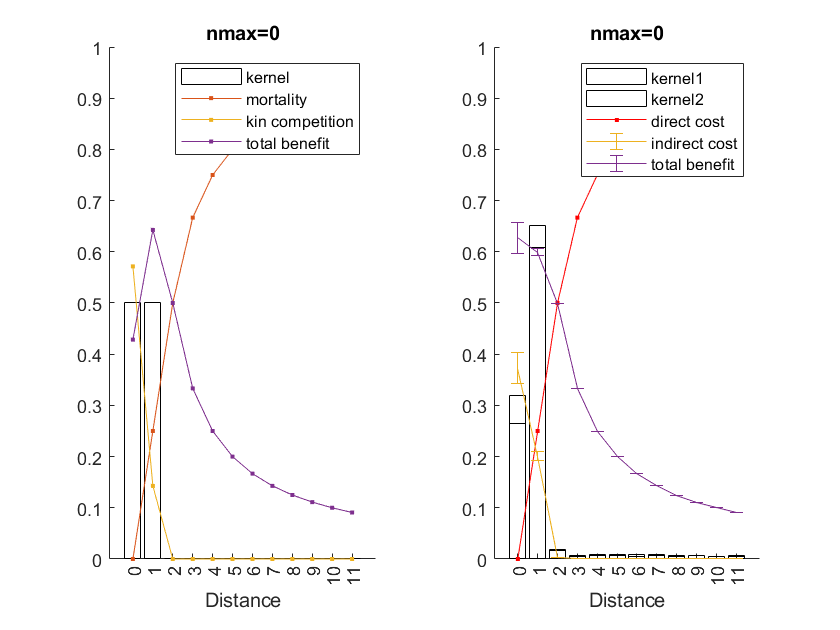

clear
clf
tiledlayout(1,2)

nexttile
v_init = [0.5 0.5 0.5 zeros(1,9)];

kernelcosts(v_init,1,1);

nexttile
load('../output_simulations/20220805/pop_nmax=1.mat')
v = mean(pop(:,1:12));
load('../output_simulations/20220805/dtime_avg_nmax=1.mat')
kernelcosts_error(v,dtime_avg,2,1,1);

### Apply it, when nmax=2

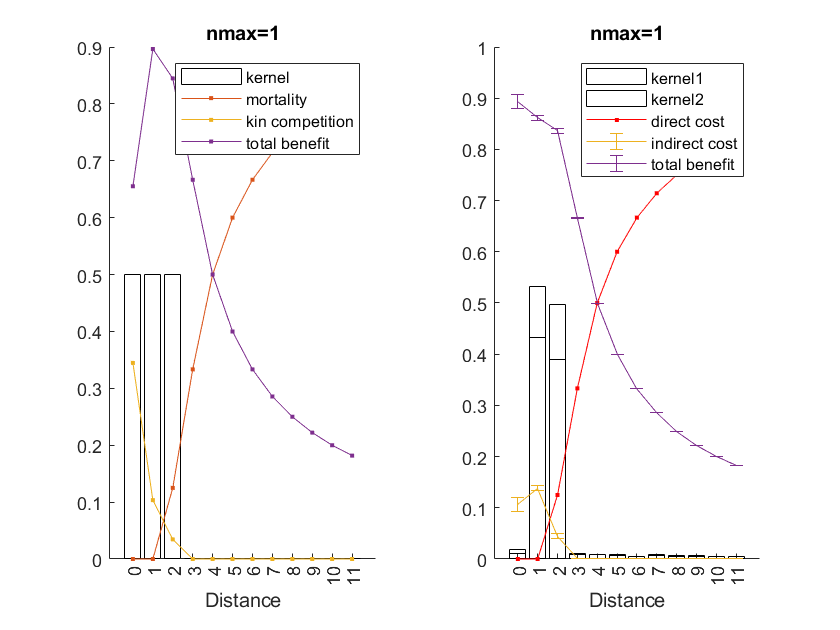

clear
clf
tiledlayout(1,2)

nexttile
v_init = [0.5 0.5 0.5 0.5 zeros(1,8)];

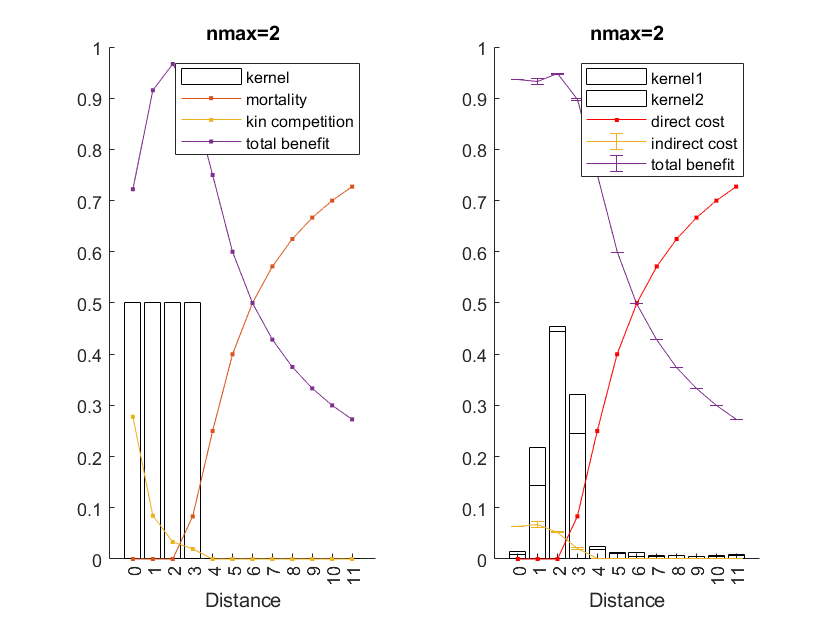

kernelcosts(v_init,2,1);

nexttile
load('../output_simulations/20220805/pop_nmax=2.mat')
v = mean(pop(:,1:12));
load('../output_simulations/20220805/dtime_avg_nmax=2.mat')
kernelcosts_error(v,dtime_avg,2,2,1);

### Interpretation

As nmax increases, the mortality cost at longer distances becomes less severe, so parents can allocate more larvae to longer distances -- reducing kin competition.

The cost due to kin competition is drastically reduced from the starting to the ending ("ESS") kernel when nmax=1,2. When nmax=0, the reduction is much more modest. (Because further reduction in kin competition, by increasing displacement distances, would increase the number of larvae paying very high mortality costs.)

Our expectation about the total benefit being equal across distances at ESS is nearly met. 